clear all

dates1 = ["01-July-2019", "01-August-2019", "01-September-2019", ...
    "01-October-2019", "01-November-2019", "01-December-2019"];

dates2 = ["01-August-2014", "01-August-2015", "01-August-2016", "01-August-2017", ... 
    "01-August-2018", "01-August-2019", "01-August-2020"];

dates3= ["01-July-2015", "01-July-2016", "01-July-2017", ... 
    "01-July-2018", "01-July-2019", "01-July-2020"];

dates4 = ["01-August-2016", "01-September-2016", "01-August-2017", "01-September-2017", ...
    "01-August-2018", "01-September-2018", "01-August-2019",...
    "01-September-2019",  "01-August-2020", "01-September-2020",];

dates5 = [ "01-August-2016", "01-September-2017", "01-September-2018"];


dates6 = ["01-January-2017", '01-February-2017', '01-March-2017', '01-April-2017', '01-May-2017', '01-June-2017', '01-July-2017', '01-August-2017', '01-September-2017', '01-October-2017', '01-November-2017', '01-December-2017', '01-January-2018', '01-February-2018', '01-March-2018', '01-April-2018', '01-May-2018', '01-June-2018', '01-July-2018', '01-August-2018', '01-September-2018', '01-October-2018', '01-November-2018', '01-December-2018', '01-January-2019', '01-February-2019', '01-March-2019', '01-April-2019', '01-May-2019', '01-June-2019', '01-July-2019', '01-August-2019', '01-September-2019', '01-October-2019', '01-November-2019', '01-December-2019' ];

dates7 = [
    "01-January-2018", "01-February-2018", "01-March-2018", "01-April-2018", "01-May-2018", "01-June-2018", "01-July-2018", "01-August-2018", "01-September-2018", "01-October-2018", "01-November-2018", "01-December-2018", ...
    "01-January-2019", "01-February-2019", "01-March-2019", "01-April-2019", "01-May-2019", "01-June-2019", "01-July-2019", "01-August-2019", "01-September-2019", "01-October-2019", "01-November-2019", "01-December-2019", ...
    "01-January-2020", "01-February-2020", "01-March-2020", "01-April-2020", "01-May-2020", "01-June-2020", "01-July-2020", "01-August-2020", "01-September-2020"];



dates = dates7;

lat_vet = {};
long_vet = {};

for date = dates
    initial_date = date;
    final_date = date;
    run('DataMask.m');
    
    lat = [];
    long = [];
    
    %% i am appending only the data that are in the square I choose (by requiring test(i) == i)
    for i = 1:length(test)
        if test(i) == 1
            lat = [lat, tmp(i,2)];
            long = [long, tmp(i,1)];
        end 
    end 

    lat_vet = [lat_vet, {lat}];
    long_vet = [long_vet, {long}];
end 


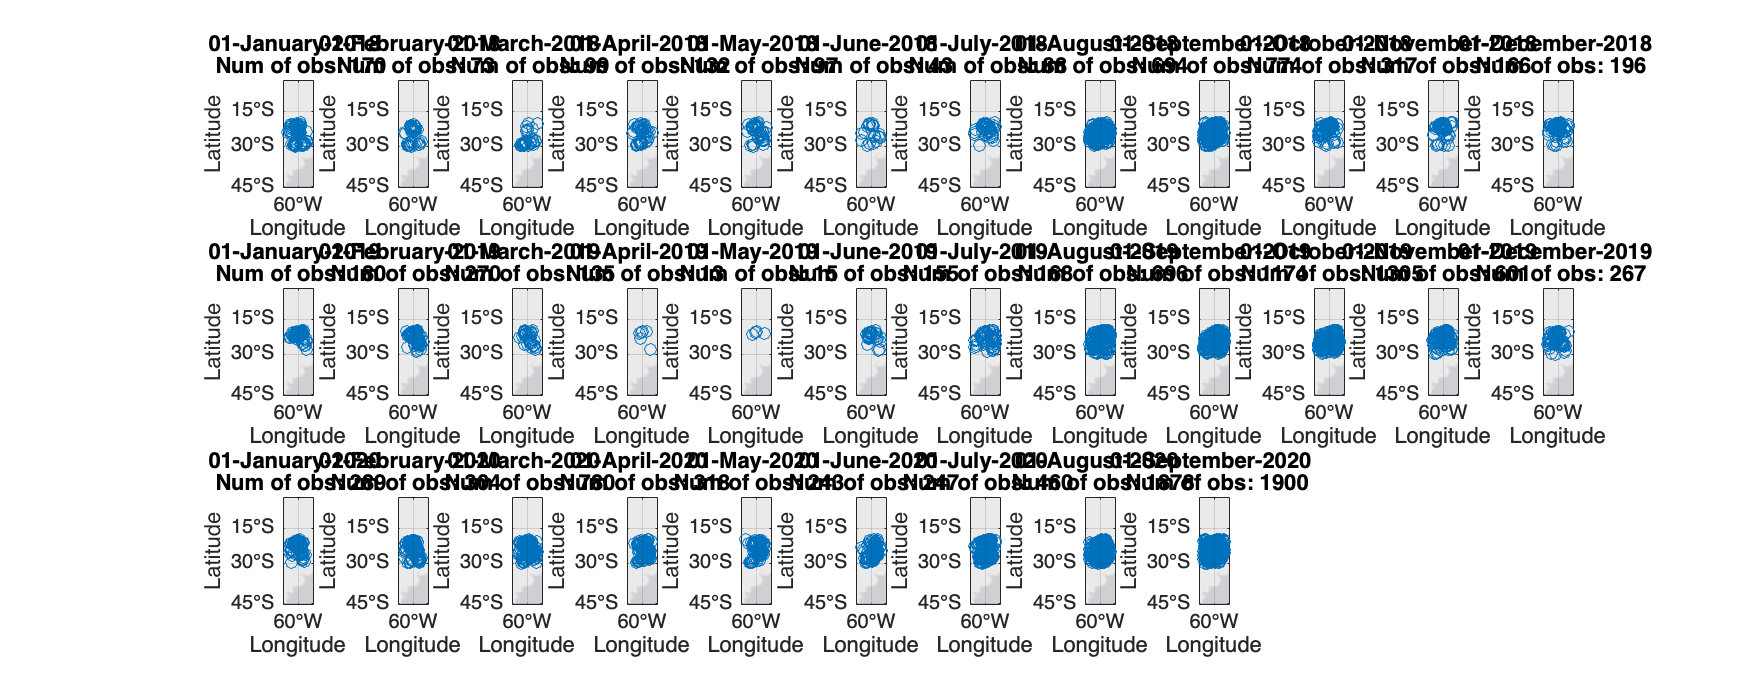

date = "01-January-2018"

date = "01-February-2018"

date = "01-March-2018"

date = "01-April-2018"

date = "01-May-2018"

date = "01-June-2018"

date = "01-July-2018"

date = "01-August-2018"

date = "01-September-2018"

date = "01-October-2018"

date = "01-November-2018"

date = "01-December-2018"

date = "01-January-2019"

date = "01-February-2019"

date = "01-March-2019"

date = "01-April-2019"

date = "01-May-2019"

date = "01-June-2019"

date = "01-July-2019"

date = "01-August-2019"

date = "01-September-2019"

date = "01-October-2019"

date = "01-November-2019"

date = "01-December-2019"

date = "01-January-2020"

date = "01-February-2020"

date = "01-March-2020"

date = "01-April-2020"

date = "01-May-2020"

date = "01-June-2020"

date = "01-July-2020"

date = "01-August-2020"

date = "01-September-2020"

figure('Position', [100, 100, 1000, 400]) 
% Tracciamento dei punti
for i=1:length(dates)
    date = dates(i)
    subplot(3, 12, i)
    geoplot(lat_vet{i}, long_vet{i}, 'o'); % Traccia i punti utilizzando marcatori circolari (o)
    geolimits([-latmax, -latmin],[-longmax, -longmin])
    titolo = sprintf('%s \n Num of obs: %d', date, length(lat_vet{i}));

    title(titolo); % Aggiunge un titolo al grafico
    % Imposta i limiti della latitudine e della longitudine
    latlim = [-32, -18];
    lonlim = [-67,-53];
    geolimits(latlim, lonlim)
end

save('/Users/edotarci/Desktop/tesi/xerox scan/data/multi_lat_vet.mat', 'lat_vet')
save('/Users/edotarci/Desktop/tesi/xerox scan/data/multi_long_vet.mat', 'long_vet')

months = table(dates');
writetable(months, '/Users/edotarci/Desktop/tesi/xerox scan/data/multi_months.csv', 'Delimiter', ',');